# Pruebas - Deep PSO

*Autor: Eduardo Andrés Santizo Olivet (16089)*

## Setup de Path

% Setup del path de trabajo. Cambiar según el directorio a utilizar.
cd 'E:/Escritorio/Temporal/Documentos/Tesis/Reinforcement y Deep Learning/Codigo/Matlab/Eduardo Santizo'

% Se incluyen todas las subcarpetas dentro de los fólderes "Funciones" y
% "Mapas" del "Path" actual. De esta manera se pueden usar las funciones 
% y datos dentro de estas carpetas aunque no estén directamente dentro del
% mismo Path local.
addpath(genpath('Funciones'));
addpath(genpath('Mapas'));
addpath(genpath('Ejemplos y Scripts Auxiliares'));
addpath(genpath('Deep PSO Tuner'));
addpath(genpath('Webots'));

% Chequea si no existen errores de sintaxis en el archivo
% "functionSignatures.json" utilizado para generar sugerencias
% personalizadas para las funciones del Toolbox.
validateFunctionSignaturesJSON;

validateFunctionSignaturesJSON completed without producing any messages.


## Limpieza de Workspace

% Limpieza de Workspace
clear;                                              % Se limpian las variables del workspace

## Cargar Dataset y Modelo de Red Entrenado

% Se cargan los datasets
load("Deep PSO Tuner\Datasets\PSO_TestDataset - Input.mat");     
load("Deep PSO Tuner\Datasets\PSO_TestDataset - Output.mat");   
load("Deep PSO Tuner\Datasets\PSO_TrainDataset - Input.mat");     
load("Deep PSO Tuner\Datasets\PSO_TrainDataset - Output.mat");   

% Se cargan los modelos de red.
load("Deep PSO Tuner\Modelos\BiLSTM - Modelo.mat");  
load("Deep PSO Tuner\Modelos\LSTM - Modelo.mat");  
load("Deep PSO Tuner\Modelos\GRU - Modelo.mat");  

## Limpieza de Variables Persistentes

clear ComputeInertia;                               % Se limpian las variables persistentes dentro de "ComputeInertia.m"
clear CostFunction;                                 % Se limpian las variables persistentes dentro de "CostFunction.m"
clear getCriteriosConvergencia;                     % Se limpia la posición previa de entidad dentro de "getCriteriosConvergencia.m"

BiLSTM = resetState(BiLSTM);                              % Se reinicia el estado interno de las redes neuronales.
LSTM = resetState(LSTM);
GRU = resetState(GRU);

## Parámetros y Settings

% Método a utilizar. 
% Escribir "help CostFunction" para más información sobre algunos de los
% métodos (Como APF, Banana, etc).
CostFunc = "Griewank";                      

% Dimensiones de Mesa de Trabajo
AnchoMesa = 20;                                     % Ancho de la mesa de simulación (Metros)
AltoMesa = 20;                                      % Alto de la mesa de simulación (Metros)
LimsX = [-AnchoMesa/2 AnchoMesa/2]';                % Posiciones mínima y máxima para el eje X (Dado el tamaño de la mesa)
LimsY = [-AltoMesa/2 AltoMesa/2]';                  % Posiciones mínima y máxima para el eje Y (Dado el tamaño de la mesa)
Margen = 0.4;                                       % Ancho de margen uniforme alrededor de los bordes de la mesa

% Settings de Simulación
EndTime = 15;                                       % Duración de algoritmo en segundos 
dt = 0.07;                                          % Tiempo de muestreo, diferencial de tiempo o "time step"
IteracionesMax = ceil(EndTime / dt);                % Iteraciones máximas que podrá llegar a durar la simulación.

% Settings de Partículas PSO
NoParticulas = 1000;                                % No. de partículas en PSO
NoPartDims = 2;                                     % No. de dimensiones para las posiciones y velocidades de las partículas
CriterioPart = "Entidades Detenidas";                % Criterio de convergencia a evaluar para las partículas
Restriccion = "Inercia";                 % Tipo de restricción a utilizar en la regla de actualización de velocidad en el PSO.     

% Generación de Estadísticas Comparativas
StatsComparacion = 0;
NoMuestras = 50;

% Settings del Neural Network Tuner
PSOTuner = 1;
NoMuestras = 5;                                     % Número de feature vectors pasados simultáneamente a la red neuronal.
ControlarParams = 1;                                % La red neuronal cobra control sobre los valores de W, Phi1 y Phi2
ModeloNN = "LSTM";

% Modo de Visualización de Animación
ModoVisualizacion = "3D";           % Modo de visualización: 2D, 3D o None.
EnableRotacionCamara = 0;                           % El plot 3D gira automáticamente
VelocidadRotacion = 0.2;                            % Velocidad con la que gira el plot

% Formatos de Guardado para Animación
SaveFrames = 0;                                     % Guardar animación como una secuencia de imágenes individuales.
SaveVideo = 0;                                      % Guardar animación como un video en formato mp4. 
SaveGIF = 0;                                        % Guardar animación como un gif.
SaveFigures = 0;                                    % Guardar todas las figuras generadas en el script actual
EnableAnotacion = 1;                                % Texto agregado al final del nombre de los archivos en caso el usuario desee agregar una nota

AnotacionOutputMedia = "_Overfitting";                               
PathGIF = ".\Output Media\GIFs\";                   % Carpeta en la que se guardarán los GIFs generados
PathVideo = ".\Output Media\Video\";                % Carpeta en la que se guardarán los videos generados
PathFrames = ".\Output Media\Frames\";              % Carpeta en la que se guardarán las frames generadas
PathFiguras = ".\Output Media\Figuras\";            % Carpeta en la que se guardarán las figuras generadas
    
% Replicabilidad de Resultados (Seed Settings)
% La seed consiste del número que se utiliza para generar los valores
% aleatorios en el programa. Si el usuario coloca un seed "manualmente"
% entonces siempre se generarán los mismos valores "aleatorios". Si no se
% proporciona un valor, Matlab elige una seed al azar y los resultados
% cambian.  
SeedManual = 0;                                     % El usuario sobre-escribirá la seed elegida por Matlab
Seed = 20185;                                       % Seed que se desea que el generador de números aleatorios emplee.

if SeedManual                   
    rng(Seed);                                      % Si SeedManual == 1, se le da un valor a la función "rng()"
else
    Seed = rng();                                   % Si SeedManual == 0, se extrae el valor usado por la función "rng()"
end

## Reglas de Método a Usar

% Función benchmark?
FuncionesBenchmark = ["Banana" "Dropwave" "Levy" "Himmelblau" "Rastrigin" "Schaffer F6" "Sphere" "Booth" "Ackley" "Griewank"];
if contains(CostFunc,FuncionesBenchmark)
    isBenchmark = 1;
else
    isBenchmark = 0;
end

## Obstáculos en Mesa de Trabajo

% Marco alrededor de mesa de trabajo.
%   - MarcoInterior = Borde interior del marco completo.
%   - MarcoExterior = Borde exterior del marco completo.
%   - Marco = Combinación de los dos polígonos en una única figura.
MarcoInterior = [LimsX(1) LimsX(1) LimsX(2) LimsX(2) LimsX(1); 
                 LimsY(1) LimsY(2) LimsY(2) LimsY(1) LimsY(1)]';
MarcoExterior = [LimsX(1)-Margen LimsX(1)-Margen LimsX(2)+Margen LimsX(2)+Margen LimsX(1)-Margen;
                 LimsY(1)-Margen LimsY(2)+Margen LimsY(2)+Margen LimsY(1)-Margen LimsY(1)-Margen]';
Marco = [MarcoInterior;
         MarcoExterior];
MarcoAltura = [zeros(size(Marco,1),1) ones(size(Marco,1),1)];
                    
% Tipo de obstáculo a colocar en el espacio de tarea. Opciones:
%   - Poligono: El usuario puede dibujar el obstáculo
%   - Cilindro: Círculo o cilindro en el centro de la mesa
%   - Imagen: Mapa en blanco y negro de imagen. Colocar la imagen en el
%     Path del toolbox (Misma carpeta tonde está SR_Toolbox.mlx). Una 
%     vez importado puede ser borrado.
%   - Caso A: Caso A del trabajo de investigación de Cahueque J.
%   - Caso B: Caso B del trabajo de investigación de Cahueque J.
%   - Caso C: Caso C del trabajo de investigación de Cahueque J.
TipoObstaculo = "Cilindro";
RadioObstaculo = 1;                                                     % Únicamente válido para el obstáculo tipo "Cilindro"
AlturaObstaculo = 1;
OffsetObstaculo = 0;
Meta = [-3 3];

switch TipoObstaculo
    
    case "Poligono"
        [XObs,YObs,ZObs] = DrawObstacles(TipoObstaculo, AlturaObstaculo, OffsetObstaculo, LimsX, LimsY, Meta, Bordes_RegionPartida);
        
    case "Cilindro"
        [XObs,YObs,ZObs] = DrawObstacles(TipoObstaculo, AlturaObstaculo, OffsetObstaculo, RadioObstaculo);
    
    case "Imagen"
        NombreImagen = "Jabandzic 1.png";
        [XObs,YObs,ZObs] = DrawObstacles(TipoObstaculo, AlturaObstaculo, OffsetObstaculo, NombreImagen);
        
        ImagenMapa = imread(".\Mapas\Imágenes\" + NombreImagen);        % Se lee la imagen deseada (Ahora guardada en "Mapas").
        SizeMapa = size(ImagenMapa);                                    % Se extraen las dimensiones de la imagen
        XObs = interp1([0 SizeMapa(2)],[LimsX(1) LimsX(2)],XObs);       % Map: Rango origen = (0, AnchoImagen) / Rango objetivo = (LimiteInferiorX, LimiteSuperiorX)
        YObs = interp1([0 SizeMapa(1)],[LimsY(1) LimsY(2)],YObs);       % Map: Rango origen = (0, AltoImagen) / Rango objetivo = (LimiteInferiorY, LimiteSuperiorY)
        
    case "Caso A"
        XObs = [-2 -2 0 0 -2]'; 
        YObs = [-7 7 7 -7 -7]';
        XObs = interp1([-10 10],[LimsX(1) LimsX(2)],XObs);
        YObs = interp1([-10 10],[LimsY(1) LimsY(2)],YObs);
        [XObs,YObs,ZObs] = DrawObstacles("Custom",AlturaObstaculo,OffsetObstaculo,XObs, YObs);
    
    case "Caso B"
        XObs = [ 0 0 2  2  0]'; 
        YObs = [-2 2 2 -2 -2]';
        XObs = interp1([-10 10],[LimsX(1) LimsX(2)],XObs);
        YObs = interp1([-10 10],[LimsY(1) LimsY(2)],YObs);
        [XObs,YObs,ZObs] = DrawObstacles("Custom",AlturaObstaculo,OffsetObstaculo,XObs, YObs);
        
    case "Caso C"
        Meta = [-3 0];
        XObs = [-6 -6 -5 -5 -6 NaN -6 -6 -5 -5 -6 NaN -1 -1 0  0 -1 NaN]';
        YObs = [-5 -4 -4 -5 -5 NaN  5  4  4  5  5 NaN -1  0 0 -1 -1 NaN]';
        XObs = interp1([-10 10],[LimsX(1) LimsX(2)],XObs);
        YObs = interp1([-10 10],[LimsY(1) LimsY(2)],YObs);
        [XObs,YObs,ZObs] = DrawObstacles("Custom",AlturaObstaculo,OffsetObstaculo,XObs, YObs);
end

## Setup PSO

### Parámetros Ambientales (Environment Parameters)

Según el tipo de función de costo a utilizar, la función puede llegar a requerir de más o menos parámetros. Funciones Benchmark no requieren parámetros adicionales, pero por ejemplo la función de APF requiere de parámetros como los vértices de los obstáculos (XObs / YObs), las posiciones máxima y mínima de la mesa de trabajo o robotat (LimsX / LimsY) y el punto de meta (Meta). Jabandzic requiere de aún más parámetros. Entonces para darle mayor flexibilidad al usuario, este puede definir en el switch case presente más adelante, la cantidad de parámetros adicionales que le desea pasar a la función de costo programada. Este solo debe tomar en cuenta los inputs adicionales en el input parser de la función `CostFunction.m`

% Parámetros adicionales para funciones de costo no estándar
switch CostFunc
    case "APF"
        EnvironmentParams = {XObs(:,1), YObs(:,1), LimsX, LimsY, Meta};
          
    otherwise
        EnvironmentParams = {};
end

### Barrido de la Superficie de Costo

Se extrae una muestra de todas las parejas coordenadas presentes en el espacio de trabajo. Luego, se evalúan todas estas parejas de coordenadas en la función de costo elegida, generando la superficie de costo. Siempre debe realizarse este paso previo a inicializar los algoritmos de optimización ya que en el caso de algunos métodos (APF por ejemplo) la función de costo debe ser inicializada previo a poder ser utilizada. 

% Imaginar que se tiene un plano coordenado que en X se extiende desde LimsX(1) hasta 
% LimsX(2), y en Y desde LimsY(1) hasta LimsY(2). En este plano existe una red de puntos
% distribuidos equitativamente a lo largo del mismo. La distancia en X y Y entre cada 
% punto es igual a "Resolución". Entonces, MeshX consiste de todas las coordenadas X de 
% esos puntos y MeshY consiste de todas las coordenadas Y de esos puntos. 
Resolucion = 0.1;
[MeshX, MeshY] = meshgrid(LimsX(1)-Margen:Resolucion:LimsX(2)+Margen, ...
                          LimsY(1)-Margen:Resolucion:LimsY(2)+Margen);

% Se redimensionan MeshX y MeshY como vectores columna y luego se concatenan. El resultado 
% es una matriz de dos columnas (Coordenadas X y Y) donde las filas consisten de todas las 
% posibles combinaciones de coordenadas que pueden existir en el plano de búsqueda. 
Mesh2D = [MeshX(:) MeshY(:)];

% Cálculo de superficie de costo inicial. La meta correspondiente a la
% función de costo varía según el tipo de función de costo.
if isBenchmark
    % Se toma la meta de la función 
    [CostoPart, Meta] = CostFunction(Mesh2D, CostFunc, EnvironmentParams{:});

else
    % Meta permanece inalterada.
    CostoPart = CostFunction(Mesh2D, CostFunc, EnvironmentParams{:});
end

% Evaluación de todas las coords. del plano en la "Cost Function". 
% El "output vector" (Nx1) se redimensiona a la forma de MeshX  
SuperficieCosto = reshape(CostoPart, size(MeshX, 1), size(MeshX, 2));                            


### Inicialización de PSO y Restricciones de Algoritmo

Se crea un objeto de tipo PSO(). Este contiene todos los parámetros necesarios para correr el algoritmo. Además, se establecen las condiciones de restricción a utilizar para la regla de actualización de la velocidad. Para más información escribir  `help PSO`  en consola.

% Creación del objeto "Part"
Part = PSO(NoParticulas, NoPartDims, CostFunc, CriterioPart, IteracionesMax, [LimsX'; LimsY']);

% Inicialización de las posiciones, velocidades y costo
Part.InitPSO(EnvironmentParams);

% Selección de restricciones para la actualización de la velocidad.
% Existen tres opciones disponibles.
%   - "Restriccion": Utilizar el coeficiente de constricción (Chi) 
%     limitando Vmax a Xmax
%   - "Inercia": Utilizar un coeficiente de inercia limitando Vmax 
%     a un valor elegido por el usuario
%   - "Mixto": Mezclar ambos métodos. Método utilizado por Aldo 
%     Nadalini en su tésis. 
Part.SetRestricciones(Restriccion,LimsX,LimsY);    

## Setup: Gráficas

if ~strcmp(ModoVisualizacion, "None")
    
    % Colores a Utilizar (En tripletes RGB normalizados: Valores de 0 a 1)
    Naranja = [0.9290 0.6940 0.1250];
    
    % Creación de figura principal
    close all;                                                                  % Se cierra cualquier ventana que Matlab tenga abierta
    MainFigure = figure('Name',"Simulación Mobile Robotics");                   % Se crea la figura principal denominada "Simulación Mobile Robotics".
    set(MainFigure,'NumberTitle',"off");                                        % Se elimina del título de la figura la parte de "Figura 1: ..."
    set(MainFigure,'visible','on');                                             % Opcional. Utilizado para mostrar animaciones en un ".mlx". Si se utiliza un ".m" se puede comentar.
    
    % Dimensiones deseadas de figura
    FigureWidth = 700;                                                          % Ancho del plot en pixeles
    FigureHeight = 500;                                                         % Alto del plot en pixeles
    ScreenSize = get(0,'ScreenSize');                                           % Se obtiene el tamaño de la pantalla física. 
    ScreenWidth = ScreenSize(3);                                                % ScreenSize(3) = Ancho pantalla
    ScreenHeight = ScreenSize(4);                                               % ScreenSize(4) = Alto pantalla
    
    % Centra la figura en pantalla
    set(MainFigure, 'Position',  [ScreenWidth/2 - FigureWidth/2, ScreenHeight/2 - FigureHeight/2, FigureWidth, FigureHeight])
    
    % Creación del axis principal o "Main Plot"
    MainPlot = gca;                                                             % Se guardan los settings de los ejes actuales ("Get current axis")

    % Leyenda inicialmente vacía
    LeyendaTexto = [];
    LeyendaHandles = []; 
    
    % Anotación: Detalles de Simulación
    DetallesPlot = {"Función Costo: " + CostFunc ; ...
                    "Tiempo Máx Simulación: " + num2str(IteracionesMax * dt) + "s"; ...
                    " " ; ...
                    "No. Partículas: " + num2str(NoParticulas) ; ... 
                    "Tipo Restricción PSO: " + Restriccion; ...
                    "PSO Tuner: " + bin2OnOff(PSOTuner); ...
                    " " ; ...
                    "Phi 1: " + num2str(Part.Phi1); ...
                    "Phi 2: " + num2str(Part.Phi2); ...
                    "Tipo Inercia: " + Part.TipoInercia; ...
                    " " ; ...
                    "Criterio Conv. Partículas: " ; ...
                    CriterioPart };
    
    % Gráficado de elementos
    switch ModoVisualizacion
        case "2D"

            % Settings de graficación para Main Plot
            hold on; grid minor; box on; axis equal;
            
            % Superficie de costo 
            PlotSupCosto = contour(MeshX, MeshY, SuperficieCosto,'HandleVisibility','off'); 
            alpha 0.5;                                                                                                    
            
            % Posición Partículas
            PlotParticulas = scatter(Part.Posicion_Actual(:,1), Part.Posicion_Actual(:,2),[],'black'); 
            LeyendaTexto = [LeyendaTexto "Partículas PSO"];
            LeyendaHandles = [LeyendaHandles PlotParticulas(1)];
            
            % Meta a alcanzar
            PlotPuntoMeta = scatter(Meta(:,1), Meta(:,2), 60, 'red', 'x','LineWidth',2);
            LeyendaTexto = [LeyendaTexto "Meta"];
            LeyendaHandles = [LeyendaHandles PlotPuntoMeta(1)];
            
            % Marco alrededor de mesa
            PolyMarco = polyshape(Marco(:,1), Marco(:,2));
            PlotMarco = plot(PolyMarco,'FaceColor','blue','FaceAlpha',0.2);
            
            % Si la función no es benchmark, se plotean los obstáculos
            if ~isBenchmark 
                PolyObs = polyshape(XObs(:,1),YObs(:,1));
                PlotObs = plot(PolyObs,'FaceColor','blue','FaceAlpha',0.2);
            end    
                     
            % Leyenda final
            Leyenda = legend(MainPlot,LeyendaHandles,LeyendaTexto,'Location',"bestoutside");
            
            % Se acota y re-dimensiona el main plot luego de graficar todo.
            % Matlab resetea los settings del axis cada vez que se grafica
            % algo, entonces es necesario setearlo al final.
            PosicionMainPlot = MainPlot.Position;
            set(MainPlot,'Position',[0.1014 0.1100 0.6 PosicionMainPlot(4)]); 
            set(MainPlot,'XLim',[LimsX(1)-Margen LimsX(2)+Margen]);
            set(MainPlot,'YLim',[LimsY(1)-Margen LimsY(2)+Margen]);
            
        case "3D"
            
            % Límites de graficación en X y Y. 
            % Z se deja libre.
            set(MainPlot,'XLim',[LimsX(1)-Margen LimsX(2)+Margen]);
            set(MainPlot,'YLim',[LimsY(1)-Margen LimsY(2)+Margen]);
            hold on; grid minor; view(3); axis manual;
            
            % Superficie de Costo
            PlotSupCosto = surf(MeshX, MeshY, SuperficieCosto,'FaceAlpha',0.6); 
            shading interp; colormap cool;  
            
            % Posición partículas
            PlotParticulas = scatter3(Part.Posicion_Actual(:,1), Part.Posicion_Actual(:,2),Part.Costo_Local,[],'black','filled'); 
            LeyendaTexto = [LeyendaTexto "Partículas PSO"];
            LeyendaHandles = [LeyendaHandles PlotParticulas(1)];
            
            % Altura Máxima Visible de Superficie Costo
            MaxAlturaVisCosto = max(SuperficieCosto(SuperficieCosto ~= Inf));
            AlturaPlanoMesa = MaxAlturaVisCosto + (MaxAlturaVisCosto * 0.5);
            zlabel(MainPlot,'Costo');
            
            if MaxAlturaVisCosto <= 0
               AlturaPlanoMesa = 1; 
            end
                
            % Piso de la mesa de trabajo 
            % (Ajustado para aparecer arriba de la función de costo)
            PlotMesa = patch(MarcoInterior(:,1), MarcoInterior(:,2),...
                             AlturaPlanoMesa*ones(size(MarcoInterior,1),1),Naranja,'FaceAlpha',0.6);
            
            % Meta a alcanzar                                 
            PlotPuntoMeta = scatter3(Meta(:,1), Meta(:,2), AlturaPlanoMesa*ones(size(Meta,1), 1),'red','x','LineWidth', 2);     
            LeyendaTexto = [LeyendaTexto "Meta"];
            LeyendaHandles = [LeyendaHandles PlotPuntoMeta(1)];
            
            % Si CostFunction no es una función Benchmark
            if ~isBenchmark
                
                % Se convierte el formato de los vértices del obstáculo
                % para ser utilizados con la función fill3.
                [XVerts,YVerts,ZVerts] = polyshape2fill3(XObs,YObs);
                
                % Ajuste para aparecer arriba de función de costo
                ZVerts = (ZVerts * 0.2 * AlturaPlanoMesa) + AlturaPlanoMesa;
                ZObs = (ZObs * 0.2 * AlturaPlanoMesa) + AlturaPlanoMesa;
           
                % Lados y tapa superior de obstáculos
                LadosObstaculos = surf(XObs,YObs,ZObs,'facecolor',Naranja,'FaceAlpha',0.6);                         
                TapaObstaculos = fill3(XVerts,YVerts,ZVerts,Naranja,'EdgeColor','k','FaceAlpha',0.6);                                                      
                       
            end
            
            % Marco de Mesa 
            % (Ajustado para aparecer arriba de la función de costo)                
            MarcoX = repmat(Marco(:,1),1,2);
            MarcoY = repmat(Marco(:,2),1,2);
            MarcoZ = (MarcoAltura * 0.3 * AlturaPlanoMesa) + AlturaPlanoMesa;

            % Paredes laterales de marco
            MarcoParedes = surf(MarcoX, MarcoY, MarcoZ,'facecolor',Naranja, 'FaceAlpha',0.6);
            
            % Tapas superior e inferior de marco
            MarcoTapa = fill3(MarcoX, MarcoY, MarcoZ, Naranja,'EdgeColor','k','FaceAlpha',0.6);        
            
            % Se ajusta el eje Z para acomodar todos los datos graficados
            set(MainPlot,'ZLimMode',"auto");
            
            % Evita que gráfica se estire sobre el eje Z al limitar la
            % relación de aspecto del eje Z. MaxAlturaPlot = Valor del 
            % tick más alto del eje Z
            LimitesEjeZ = zlim;
            MaxAlturaPlot = LimitesEjeZ(2); 
            set(MainPlot,'DataAspectRatio',[1 1 MaxAlturaPlot/15]);
            
            % Ajuste del tamaño de los axis.
            PosicionMainPlot = MainPlot.Position;
            set(MainPlot,'Position',[0.1014 0.1100 0.79 PosicionMainPlot(4)]);
            
            % Permite que el usuario rote la gráfica con el mouse
            if ~EnableRotacionCamara
                rotate3d on;  
            end
            
            % Leyenda final
            Leyenda = legend(MainPlot,LeyendaHandles,LeyendaTexto,'Location',"bestoutside");

    end
    
    % Se extrae la posición de Leyenda
    PosicionLeyenda = Leyenda.Position;
    
    % Anotación / Detalles de Gráfica
    AnotacionPlot = annotation('textbox', [PosicionLeyenda(1), PosicionLeyenda(2)-0.05, 0.22, 0],...
                               'String',DetallesPlot,'FontSize',7);   
    
    % Nombre de ejes
    xlabel(MainPlot,'X');
    ylabel(MainPlot,'Y'); 
    
    % Se desactiva el menú para interactuar con la gráfica
    set(MainFigure, 'MenuBar', 'none');
    set(MainFigure, 'ToolBar', 'none'); 
    
end

## Setup: Video / Frames / GIFs

% Estructura del nombre del GIF / Video / Folder de Frames
if PSOTuner
    NombreOutputMedia = CostFunc + "_" + Restriccion + "_" + ModeloNN;
else
    NombreOutputMedia = CostFunc + "_" + Restriccion + "_PSO Tuner Off";
end

% GIF: Settings iniciales
if SaveGIF
    
    % Nombre + Path del GIF
    NombreGIF = PathGIF + NombreOutputMedia + ".gif";

    % Se agrega la anotación especificada por el usuario al final del
    % nombre en caso la opción esté habilitada.
    if EnableAnotacion
        [PathBase,NombreArchivo,Extension] = fileparts(NombreGIF);
        NombreGIF = PathBase + "\" + NombreArchivo + AnotacionOutputMedia + Extension; 
    end
    
    % Se corrige el nombre del archivo para prevenir sobre-escritura
    NombreGIF = preventFileOverwrite(NombreGIF);

    % Se guarda la primera frame del GIF.
    Frame = getframe(MainFigure);
    [ImGIF,MapGIF] = rgb2ind(Frame.cdata,256,'nodither');
end

% Video: Settings iniciales
if SaveVideo
    
    % Nombre + Path del Video
    NombreVideo = PathVideo + NombreOutputMedia + ".mp4";

    % Se agrega la anotación especificada por el usuario al final del
    % nombre en caso la opción esté habilitada.
    if EnableAnotacion
        [PathBase,NombreArchivo,Extension] = fileparts(NombreVideo);
        NombreVideo = PathBase + "\" + NombreArchivo + AnotacionOutputMedia + Extension;  
    end
    
    % Se corrige el nombre del archivo para prevenir sobre-escritura
    NombreVideo = preventFileOverwrite(NombreVideo);
    
    % Se inicia la escritura de video
    Video = VideoWriter(NombreVideo,'MPEG-4');
    Video.FrameRate = 30;
    open(Video);
end

% Frames: Settings iniciales
if SaveFrames
    
   % Nombre + Path del Folder
   NombreFolder = PathFrames + NombreOutputMedia;
   
   % Se agrega la anotación especificada por el usuario al final del
   % nombre en caso la opción esté habilitada.
   if EnableAnotacion
       [PathBase,NombreArchivo,Extension] = fileparts(NombreFolder);
       NombreFolder = PathBase + "\" + NombreArchivo + AnotacionOutputMedia;  
   end
   
   % Se corrige el nombre del archivo para prevenir sobre-escritura
   NombreFolder = preventFileOverwrite(NombreFolder);
   
   % Se inicia la cuenta de frames para nombrarlas y guardarlas
   Frame = 0;
   
   % Cada cuantas frames se toma un screenshot. 
   % Valor recomendado = 3
   FrameSkip = 3;                                     
   
   % Se crea / limpia la carpeta de frames
   mkdir(NombreFolder);
end

## Main Loop

HistorialParams = zeros(4,IteracionesMax);

NoFeatures = size(NetInput{1},1);
MuestraActual = 1;
Muestras = ones(NoFeatures, NoMuestras) * NaN;

%DistAMeta_Norm = zeros(1,IteracionesMax);
%DiffSwarm_GB = zeros(1,IteracionesMax);
%CoherenciaSwarm = zeros(1,IteracionesMax);
%PromDistPromPartASwarm = zeros(1,IteracionesMax);
%DistPromACentro_Norm = zeros(1,IteracionesMax);

for i = 2:IteracionesMax
    
    % =========================================
    % MÉTODOS PSO
    % =========================================

    if PSOTuner
        % Medida de dispersión normalizada para la swarm
        DesvEstPosX = std(Part.Posicion_Actual(:,1)) / (AnchoMesa/2);
        DesvEstPosY = std(Part.Posicion_Actual(:,2)) / (AltoMesa/2);
        DesvEstPosMedia = mean([DesvEstPosX DesvEstPosY]);
        
        % Coherencia de la Swarm
        VelCentroSwarm = norm(mean(Part.Velocidad));                                % Velocidad del centro del swarm (Vs)
        VelPromedioParts = mean(vecnorm(Part.Velocidad,2,2));                       % Velocidad promedio de las partículas (V^linita)
        CoherenciaSwarm = (VelCentroSwarm + 0.01)/ (VelPromedioParts + 0.01);
        
        % Medida de la distancia del global best del swarm a la meta
        % (Normalizado)
        IndDistMin = dsearchn(Meta, Part.Posicion_GlobalBest);                                          % Indice de la meta más cercana al global best
        ComponenteXDist = Meta(IndDistMin,1) - Part.Posicion_GlobalBest(1);                             % Componente X de la distancia entre meta y global best
        ComponenteYDist = Meta(IndDistMin,2) - Part.Posicion_GlobalBest(2);                             % Componente Y de la distancia entre meta y global best
        DistMasLejana = hypot(LimsX(2) - abs(Meta(IndDistMin,1)), LimsY(2) - abs(Meta(IndDistMin,2)));  % Distancia más lejana que pueden tomar las partículas a la meta dada la dimensión de la mesa
        DistAMeta_Norm = hypot(ComponenteXDist, ComponenteYDist) / DistMasLejana;                       % Normalización de componentes y cálculo de distancia entre meta y global best
        
        % Promedio de la distancia Promedio de cada Partícula a todo el resto del
        % Swarm (D_all)
        MediaSwarm = mean(Part.Posicion_Actual);
        DistsEntrePartsSwarm = getDistsBetweenParticles(Part.Posicion_Actual,"Full");
        DistMasLejana = hypot(LimsX(2) - abs(MediaSwarm(1)), LimsY(2) - abs(MediaSwarm(2)));
        PromDistPromPartASwarm = mean(DistsEntrePartsSwarm,'all') / DistMasLejana;
        
        % Diámetro de Swarm (D)   
        %DistsEntrePartsSwarm = getDistsBetweenParticles(Part.Posicion_Actual,"Triangular");
        %DiametroSwarm = max(DistsEntrePartsSwarm,[],'all');
        
        % Centro de Swarm (Xk negrita y con linita arriba)
        % CentroSwarm = mean(Part.Posicion_Actual);
        
        % Distancia Promedio Normalizada alrededor del Centro del Swarm (Dn)
        % [~,DistsACentroSwarm] = dsearchn(CentroSwarm, Part.Posicion_Actual);
        % DistPromACentro_Norm(i) = mean(DistsACentroSwarm) / DiametroSwarm;

        FeatureVector = [DesvEstPosMedia;
                         CoherenciaSwarm;
                         DistAMeta_Norm;
                         PromDistPromPartASwarm];
        
        % Si aún no se ha llenado el vector de muestras o en otras palabras
        % existen "NaNs" en el array de muestra.
        if sum(isnan(Muestras),'all') > 0
            Muestras(:,MuestraActual) = FeatureVector;
            MuestraActual = MuestraActual + 1;
            
        % Si ya se llenó la matriz de muestras  
        else
            Muestras = circshift(Muestras,-1,2);        % Se corren las columnas 1 espacio a la izquierda
            Muestras(:,NoMuestras) = FeatureVector;     % Se adjunta el feature vector en la última columna
        
            switch ModeloNN
                case "BiLSTM"
                    [BiLSTM,Params] = predictAndUpdateState(BiLSTM,Muestras,'MiniBatchSize',1);
                    
                case "LSTM"
                    [LSTM,Params] = predictAndUpdateState(LSTM,Muestras,'MiniBatchSize',1);
                    
                case "GRU"
                    [GRU,Params] = predictAndUpdateState(GRU,Muestras,'MiniBatchSize',1);
            
            end
            
            if ControlarParams
                Part.W = Params(1);
                Part.Phi1 = Params(2);
                Part.Phi2 = Params(3);
            end
            
            % Historial de parámetros a optimizar
            HistorialParams(1:3,i) = Params(1:3,end);
            HistorialParams(4,i) = Params(4,end) * IteracionesMax;
            
        end

        
    else
        
        HistorialParams(1:3,i) = [Part.W; Part.Phi1; Part.Phi2];
    
    end
    
    % Ejecución de algoritmo PSO
    [StopPart] = Part.RunStandardPSO("Steps", Meta, EnvironmentParams);
    
    % =========================================
    % ACTUALIZACIÓN DE PLOTS
    % =========================================
    
    % Actualización de los plots utilizando handlers para mejorar "performance"   
    switch ModoVisualizacion
        
        case "2D"
            
            PlotPuntoMeta.XData = Meta(:,1);
            PlotPuntoMeta.YData = Meta(:,2);
            
            PlotParticulas.XData = Part.Posicion_Actual(:,1);
            PlotParticulas.YData = Part.Posicion_Actual(:,2);

        case "3D"
            
            PlotPuntoMeta.XData = Meta(:,1);
            PlotPuntoMeta.YData = Meta(:,2);
            
            PlotParticulas.XData = Part.Posicion_Actual(:,1);
            PlotParticulas.YData = Part.Posicion_Actual(:,2);
            PlotParticulas.ZData = Part.Costo_Local;
            
            if EnableRotacionCamara
                [RotacionCam,InclinacionCam] = view(MainPlot);      % Se obtiene el angulo de rotación e inclinación actual de la cámara
                RotacionCam = RotacionCam - VelocidadRotacion;      % Se disminuye el ángulo de rotación en "VelocidadRotacion"
                view(MainPlot,RotacionCam,InclinacionCam);          % Se fuerza el nuevo ángulo a la cámara
            end
    
    end
    
    % =========================================
    % TÍTULOS Y ANOTACIONES
    % =========================================
    
    % Actualización del título del main plot 
    TituloTexto = {"Tiempo de Ejecución: " + num2str(i*dt, '%4.2f') + "s"};
    title(MainPlot,TituloTexto);
    
    % =========================================
    % CRITERIOS CONVERGENCIA
    % =========================================

    % Finalización de main loop en caso de convergencia
    if StopPart || (i == IteracionesMax)
        
        % Iteraciones para que el algoritmo finalizara
        IteracionesFin = i;                             
        break;      
    end
    
    % Actualización gradual de gráficos para animación. Existen dos opciones:
    %   - drawnow: Se mira suave, pero corre más lento
    %   - drawnow limitrate: Se mira "stuttery" pero corre más rápido
    drawnow;                                                                   
    
    % =========================================
    % OUTPUT MEDIA
    % =========================================
    
    % Guardado de Frames Numeradas. La función "mod" se utiliza para
    % guardar frames luego de la cantidad especificada por "FrameSkip"
    if SaveFrames
        if mod(i,FrameSkip) == 0
            saveas(MainFigure, NombreFolder + "\" + num2str(Frame) + ".png");
            Frame = Frame + 1;
        end
    end
    
    % Escritura a Video
    if SaveVideo
        Frame = getframe(MainFigure);
        writeVideo(Video,Frame);
    end
    
    % Escritura a Gif
    if SaveGIF
        Frame = getframe(MainFigure);
        ImGIF(:,:,1,i) = rgb2ind(Frame.cdata,MapGIF,'nodither');
    end

end

% Se permite al usuario mover la cámara al finalizar la animación.
if strcmp(ModoVisualizacion,"3D")
    axis(MainPlot);
    rotate3d on;  
end

DetallesPlot{end+1} = "Iteraciones para Conv: " + num2str(IteracionesFin);
AnotacionPlot.String = DetallesPlot;   

% Finalización de video
if SaveVideo
    Frame = getframe(MainFigure);
    writeVideo(Video,Frame);
    close(Video); 
end

% Finalización de GIF
if SaveGIF
    imwrite(ImGIF,MapGIF,NombreGIF,'DelayTime',0,'LoopCount',inf) 
end

## Gráfica: Dispersión de Partículas

DispersionParts = figure('Name',"Media y Desviación Estándar de Posiciones de Marcadores PSO", 'Position', [100, 100, 800, 400]); clf;
set(DispersionParts,'Visible','on');

% Filtrado de datos para deplegar iteraciones previas a la convergencia de las partículas
Part.Posicion_History{1}(:,IteracionesFin:end) = [];                                                                        % Filtrado dimensión X
Part.Posicion_History{2}(:,IteracionesFin:end) = [];                                                                        % Filtrado dimensión Y

% Dispersión de partículas sobre eje X
PartPosMediaX = median(Part.Posicion_History{1});                                                                           % Posición X media para cada iteración
PartDesvEstX = std(Part.Posicion_History{1});                                                                               % Desviación estándar para la posición X de las partículas

subplot(1,2,1); hold on;
DesvEstX = fill([(1:IteracionesFin-1)*dt; (1:IteracionesFin-1)*dt], ...
                [PartPosMediaX - PartDesvEstX; PartPosMediaX + PartDesvEstX], 'b','EdgeColor','b','EdgeAlpha',0.1);         % Fill: Evolución de la dispersión de las partículas en el tiempo
MedianaX = plot((1:IteracionesFin-1)*dt, PartPosMediaX,'b', 'LineWidth', 3);                                                % Plot: Evolución de la mediana de todas las coords X de las partículas
AreaColorX = area([0.0001 0.0002],[0.0001 0.0002],'FaceColor','b','FaceAlpha',.3,'EdgeAlpha',.3,'ShowBaseLine','off');      % Area: Usada para que en leyenda aparezca un color similar al de las líneas del fill.

ylabel("Coordenada X Media",'FontSize',14); xlabel("Tiempo (s)");
xlim([0 (IteracionesFin-1)*dt]);
legend([MedianaX(1) AreaColorX(1)],"Media","Desv. Estándar");
grid on; grid minor;

% Dispersión de partículas sobre eje Y
PartPosMediaY = median(Part.Posicion_History{2});                                                                           % Posición Y media para cada iteración
PartDesvEstY = std(Part.Posicion_History{2});                                                                               % Desviación estándar para la posición Y de las partículas

subplot(1,2,2); hold on;

DesvEstY = fill([(1:IteracionesFin-1)*dt; (1:IteracionesFin-1)*dt], ...
                [PartPosMediaY - PartDesvEstY; PartPosMediaY + PartDesvEstY], 'r','EdgeColor','r','EdgeAlpha',0.1);         % Fill: Evolución de la dispersión de las partículas en el tiempo
MedianaY = plot((1:IteracionesFin-1)*dt, PartPosMediaY,'r','LineWidth', 3);                                                 % Plot: Evolución de la mediana de todas las coords Y de las partículas
AreaColorY = area([0.0001 0.0002],[0.0001 0.0002],'FaceColor','r','FaceAlpha',.3,'EdgeAlpha',.3,'ShowBaseLine','off');      % Area: Usada para que en leyenda aparezca un color similar al de las líneas del fill.

ylabel('Coordenada Y Media','FontSize',14); xlabel("Tiempo (s)");
xlim([0 (IteracionesFin-1)*dt]);
legend([MedianaY(1) AreaColorY(1)],"Media","Desv. Estándar");
grid on; grid minor;

## Gráfica: Parámetros Generados por la Red Neuronal

ParamsPSO = figure('Name',"Evolución de Parámetros PSO", 'Position', [100, 100, 600, 400]); clf;
set(ParamsPSO, 'Visible','on');

VectorTiempo = (1:IteracionesFin)*dt;

% Gráfica de los parámetros W, Phi1 y Phi2
subplot(2,1,1);

%plot(VectorTiempo,DiffSwarm_GB(1:IteracionesFin),'LineWidth',1.5);
%plot(VectorTiempo,CoherenciaSwarm(1:IteracionesFin),'LineWidth',1.5);
%plot(VectorTiempo, PromDistPromPartASwarm(1:IteracionesFin),'LineWidth',1.5);
%plot(VectorTiempo, DistPromACentro_Norm(1:IteracionesFin),'LineWidth',1.5);
%plot(VectorTiempo,DistAMeta_Norm(1:IteracionesFin),'LineWidth',1.5);

plot(VectorTiempo, HistorialParams(1:3,1:IteracionesFin)','LineWidth',1.5);
xlabel("Tiempo (s)"); ylabel("Valor de Parámetro");
title("Evolución de Parámetros");
legend("\omega", "\phi_1", "\phi_2");
xlim([dt IteracionesFin*dt]);
grid minor;

% Gráfica del estimado de iteraciones para converger
subplot(2,1,2); hold on;

% Medida de dispersión normalizada para la swarm
%DesvEstPosX = std(Part.Posicion_History{1}) / (AnchoMesa/2);
%DesvEstPosY = std(Part.Posicion_History{2}) / (AltoMesa/2);
%DesvEstPosMedia = mean([DesvEstPosX; DesvEstPosY]);
%plot(1:IteracionesFin-1, DesvEstPosMedia,'LineWidth',1.5);
%plot(DistAMeta_Norm(1:IteracionesFin),'LineWidth',1.5);

plot(HistorialParams(4,1:IteracionesFin)','LineWidth',1.5);
yline(IteracionesFin,'--r');
xlabel("Iteraciones"); ylabel("No Iteraciones");
title("Estimado - Tiempo de Convergencia");
legend("Estimado", "Real");
xlim([1 IteracionesFin]);
grid minor;

## Comparación entre Métodos

Se compara el desempeño entre un método sin el PSO Tuner, con el PSO Tuner (Utilizando arquitectura RNN) y con el PSO Tuner (Utilizando arquitectura LSTM). 

if StatsComparacion
    
    NombrePruebas = {'PSO Tuner: Off' 'PSO Tuner: BiLSTM' 'PSO Tuner: LSTM' 'PSO Tuner: GRU'};
    
    NoPruebas = numel(NombrePruebas);
    Pruebas = cell(5,NoPruebas);
    ProgressBar = waitbar(0,'Generando Comparaciones');
    
    % 3 pruebas a realizar
    % - Sin PSO Tuner
    % - PSO Tuner: RNN
    % - PSO Tuner: LSTM
    for i = 1:NoPruebas
            
        % Cambios según número de prueba
        switch i
            
            % Prueba 1: Sin PSO Tuner
            case 1
                PSOTuner = 0;
            
            % Prueba 2: RNN
            case 2
                PSOTuner = 1;
                ModeloNN = "BiLSTM";
                
            % Prueba 3: LSTM
            case 3
                PSOTuner = 1;
                ModeloNN = "LSTM";
                
            % Prueba 4: GRU
            case 4
                PSOTuner = 1;
                ModeloNN = "GRU";
                
        end
        
        % Se inicializa la matriz de medias, desviaciones e iteraciones
        MediasX = zeros(NoMuestras, IteracionesMax);
        MediasY = zeros(NoMuestras, IteracionesMax);
        DesviacionesX = zeros(NoMuestras, IteracionesMax);
        DesviacionesY = zeros(NoMuestras, IteracionesMax);
        Iteraciones = zeros(NoMuestras,1);
        
        % Se toman cierto "NoMuestras" para cada prueba
        for j = 1:NoMuestras
            
            % Se reinicia el estado interno de las redes neuronales.
            RNN = resetState(RNN);                              
            LSTM = resetState(LSTM);

            % Se inicializa el algoritmo PSO
            Part.InitPSO(EnvironmentParams);
            Part.SetRestricciones(Restriccion,LimsX,LimsY); 
            
            % Buffer de los feature vectors generados
            NoFeatureVectors = 2;
            NoFeatures = size(NetInput{1},1);
            FeatureVector_Actual = 1;
            Buffer_FeatureVectors = ones(NoFeatures, NoMuestras) * NaN;

            % Se inicia la simulación
            for k = 1:IteracionesMax
            
                if PSOTuner
                    % Medida de dispersión normalizada para la swarm
                    DesvEstPosX = std(Part.Posicion_Actual(:,1)) / (AnchoMesa/2);
                    DesvEstPosY = std(Part.Posicion_Actual(:,2)) / (AltoMesa/2);
                    DesvEstPosMedia = mean([DesvEstPosX DesvEstPosY]);
                    
                    % Coherencia de la Swarm
                    VelCentroSwarm = norm(mean(Part.Velocidad));                                % Velocidad del centro del swarm (Vs)
                    VelPromedioParts = mean(vecnorm(Part.Velocidad,2,2));                       % Velocidad promedio de las partículas (V^linita)
                    CoherenciaSwarm = (VelCentroSwarm + 0.01)/ (VelPromedioParts + 0.01);
                    
                    % Medida de la distancia del global best del swarm a la meta
                    % (Normalizado)
                    IndDistMin = dsearchn(Meta, Part.Posicion_GlobalBest);                                          % Indice de la meta más cercana al global best
                    ComponenteXDist = Meta(IndDistMin,1) - Part.Posicion_GlobalBest(1);                             % Componente X de la distancia entre meta y global best
                    ComponenteYDist = Meta(IndDistMin,2) - Part.Posicion_GlobalBest(2);                             % Componente Y de la distancia entre meta y global best
                    DistMasLejana = hypot(LimsX(2) - abs(Meta(IndDistMin,1)), LimsY(2) - abs(Meta(IndDistMin,2)));  % Distancia más lejana que pueden tomar las partículas a la meta dada la dimensión de la mesa
                    DistAMeta_Norm = hypot(ComponenteXDist, ComponenteYDist) / DistMasLejana;                       % Normalización de componentes y cálculo de distancia entre meta y global best
                    
                    % Promedio de la distancia Promedio de cada Partícula a todo el resto del
                    % Swarm (D_all)
                    MediaSwarm = mean(Part.Posicion_Actual);
                    DistsEntrePartsSwarm = getDistsBetweenParticles(Part.Posicion_Actual,"Full");
                    DistMasLejana = hypot(LimsX(2) - abs(MediaSwarm(1)), LimsY(2) - abs(MediaSwarm(2)));
                    PromDistPromPartASwarm = mean(DistsEntrePartsSwarm,'all') / DistMasLejana;
            
                    FeatureVector = [DesvEstPosMedia;
                                     CoherenciaSwarm;
                                     DistAMeta_Norm;
                                     PromDistPromPartASwarm];
                    
                    % Si aún no se ha llenado el vector de muestras o en otras palabras
                    % existen "NaNs" en el array de muestra.
                    if sum(isnan(Buffer_FeatureVectors),'all') > 0
                        Buffer_FeatureVectors(:,FeatureVector_Actual) = FeatureVector;
                        FeatureVector_Actual = FeatureVector_Actual + 1;
                        
                    % Si ya se llenó la matriz de muestras  
                    else
                        Buffer_FeatureVectors = circshift(Buffer_FeatureVectors,-1,2);      % Se corren las columnas 1 espacio a la izquierda
                        Buffer_FeatureVectors(:,NoFeatureVectors) = FeatureVector;          % Se adjunta el feature vector en la última columna
                    
                        switch ModeloNN
                            case "BiLSTM"
                                [BiLSTM,Params] = predictAndUpdateState(BiLSTM,Muestras,'MiniBatchSize',1);
                                
                            case "LSTM"
                                [LSTM,Params] = predictAndUpdateState(LSTM,Muestras,'MiniBatchSize',1);
                                
                            case "GRU"
                                [GRU,Params] = predictAndUpdateState(GRU,Muestras,'MiniBatchSize',1);
            
                        end
                        
                        Part.W = Params(1);
                        Part.Phi1 = Params(2);
                        Part.Phi2 = Params(3);
                    end
            
                end
                
                % Ejecución de algoritmo PSO
                Part.RunStandardPSO("Steps", Meta, EnvironmentParams);
                
                % Evaluación de criterios de convergencia
                [StopPart] = getCriteriosConvergencia("Meta Alcanzada", Meta, Part.Posicion_Actual, k/IteracionesMax,'ThresholdDist',0.1);
                
                if StopPart
                    IteracionesFin = k;
                    
                    for n = 1:2
                        HistorialInicial = Part.Posicion_History{n}(:,1:IteracionesFin);                                % Se guardan los valores hasta "IteraciónActual"
                        Part.Posicion_History{n} = Part.Posicion_Actual(:,n) .* ones(size(Part.Posicion_History{n}));   % "PosicionHistory" = Matriz del mismo tamaño de "PosicionHistory" pero formado por copias de la "Posicion_Actual"
                        Part.Posicion_History{n}(:,1:IteracionesFin) = HistorialInicial;                                % Se sobrescribe el "historial inicial" en las primeras posiciones del historial lleno de copias de "Posicion_Actual".
                    end
                    
                    break;      
                end
                
            end
            
            % Se actualiza el "log" de medias, desviaciones e iteraciones
            MediasX(j,:) = mean(Part.Posicion_History{1});
            MediasY(j,:) = mean(Part.Posicion_History{2});
            DesviacionesX(j,:) = std(Part.Posicion_History{1});
            DesviacionesY(j,:) = std(Part.Posicion_History{2});
            Iteraciones(j) = Part.IteracionActual;
              
            % Se actualiza la barra de progreso
            waitbar(((i-1)*NoMuestras + j) / (NoPruebas*NoMuestras));
            
        end
        
        % Se agregan todos los "logs" a la columna correspondiente a la
        % prueba actual.
        Pruebas(:,i) = {MediasX ; MediasY ; DesviacionesX ; DesviacionesY ; Iteraciones};
        
    end
    
    % Se cierra la barra de progreso
    close(ProgressBar);
    
    % Comparación de Iteraciones
    Pruebas_Iter = cell2mat(Pruebas(5,:));
    figure('Name',"Comparación: Iteraciones"); clf;
    boxplot(Pruebas_Iter,'Labels', NombrePruebas);
    title("Comparación: Iteraciones para Converger");
    ylabel("No Iteraciones");
    
    % Comparación de dispersión
    figure('Name',"Comparación: Dispersión y Media", 'Position',[100, 100, 1024, 700]); clf;

    for i = 1:NoPruebas
        
        % Iteración máxima para cada prueba.
        Pruebas_IterMax = round(mean(Pruebas_Iter),0);
        
        % Dispersión de partículas sobre eje X
        Pruebas_MediaX = median(cell2mat(Pruebas(1,i)));    % Posición X media para cada iteración
        Pruebas_DesvX = std(cell2mat(Pruebas(3,i)));        % Desviación estándar para la posición X de las partículas
        
        % Se acota la media y dispersión
        Pruebas_MediaX = Pruebas_MediaX(1:Pruebas_IterMax(i));
        Pruebas_DesvX = Pruebas_DesvX(1:Pruebas_IterMax(i));
        
        % Conversión de iteraciones a tiempo
        VectorTiempo = (1:Pruebas_IterMax(i))*dt;
        
        % Suplot: Dispersión X
        % Posición: Fila i, Columna 1
        subplot(NoPruebas,2,(i-1)*2 + 1); hold on;
        
        DesvEstX = fill([VectorTiempo; VectorTiempo], ...
                        [Pruebas_MediaX - Pruebas_DesvX; Pruebas_MediaX + Pruebas_DesvX], ...
                        'b','EdgeColor','b','EdgeAlpha',0.1);         
        MediaX = plot(VectorTiempo, Pruebas_MediaX,'b', 'LineWidth', 3);                                                
        AreaColorX = area([0.0001 0.0002],[0.0001 0.0002],'FaceColor','b','FaceAlpha',.3,'EdgeAlpha',.3,'ShowBaseLine','off');      
        
        ylabel(NombrePruebas(i)); xlabel("Tiempo (s)");
        xlim([dt Pruebas_IterMax(i)*dt]); 
        grid minor;
        
        % Título de columna
        if i == 1
            title("Dispersión Coodenadas X");
        end
        
        % Dispersión de partículas sobre eje Y
        Pruebas_MediaY = median(cell2mat(Pruebas(2,i)));    % Posición X media para cada iteración
        Pruebas_DesvY = std(cell2mat(Pruebas(4,i)));        % Desviación estándar para la posición X de las partículas
        
        % Se acota la media y dispersión
        Pruebas_MediaY = Pruebas_MediaY(1:Pruebas_IterMax(i));
        Pruebas_DesvY = Pruebas_DesvY(1:Pruebas_IterMax(i));
        
        % Suplot: Dispersión Y
        % Posición: Fila i, Columna 2
        subplot(NoPruebas,2,(i-1)*2 + 2); hold on;
        
        DesvEstY = fill([VectorTiempo; VectorTiempo], ...
                        [Pruebas_MediaY - Pruebas_DesvY; Pruebas_MediaY + Pruebas_DesvY], ...
                        'b','EdgeColor','r','EdgeAlpha',0.1);         
        MediaY = plot(VectorTiempo, Pruebas_MediaY,'r', 'LineWidth', 3);                                                
        AreaColorY = area([0.0001 0.0002],[0.0001 0.0002],'FaceColor','r','FaceAlpha',.3,'EdgeAlpha',.3,'ShowBaseLine','off');      
        
        xlabel("Tiempo (s)");
        xlim([dt Pruebas_IterMax(i)*dt]); 
        grid minor;
        
        % Título de columna
        if i == 1
            title("Dispersión Coodenadas Y");
        end
        
    end
    
    sgtitle({"Comparación Métodos" ; "Función Costo: " + CostFunc + " / Restricción: " + Restriccion});
    
end

## Guardando Todas las Figuras Generadas

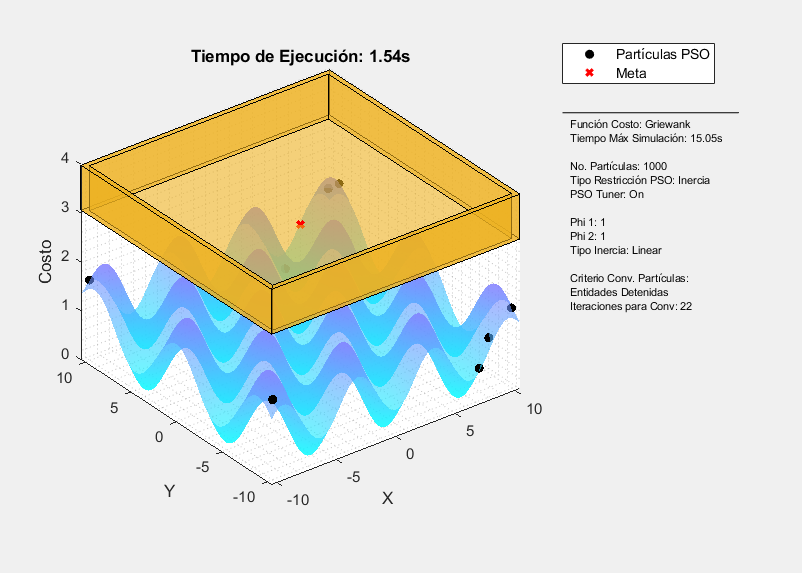

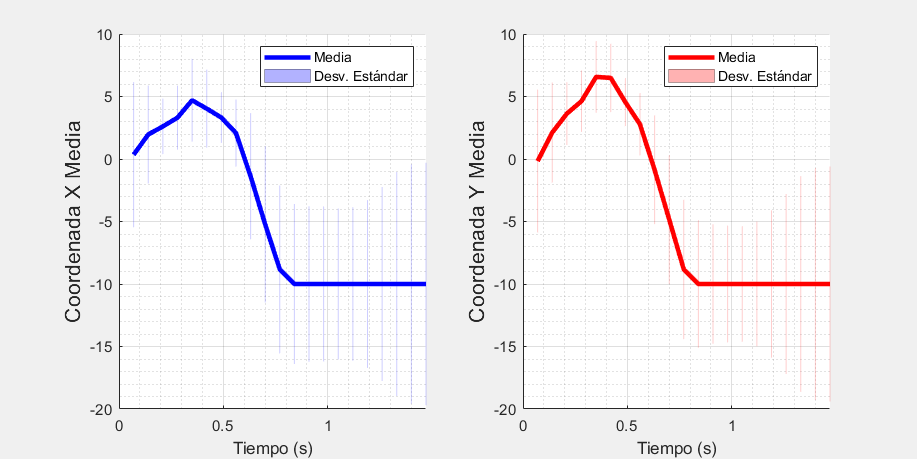

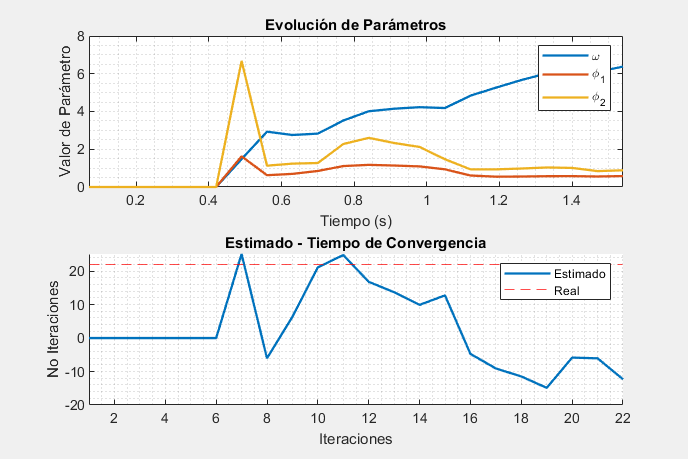

if SaveFigures

    % Nombre del folder donde se guardarán las figuras
    NombreFolder = PathFiguras + NombreOutputMedia;
    
    % Se agrega la anotación especificada por el usuario al final del
    % nombre en caso la opción esté habilitada.
    if EnableAnotacion
      NombreFolder = NombreFolder + AnotacionOutputMedia; 
    end
    
    % Se guardan las figuras generadas
    saveWorkspaceFigures(NombreFolder,"png");
end

## Prueba 1: Entrenamiento de Red con Neuronas GRU

No funcionó. Al parecer Matlab toma toda la data de un solo, lo que causa que, para datasets muy grandes el jacobiano numérico que calcula para hacer backpropagation se vuelva muy grande, causando que Matlab crashee por falta de memoria.

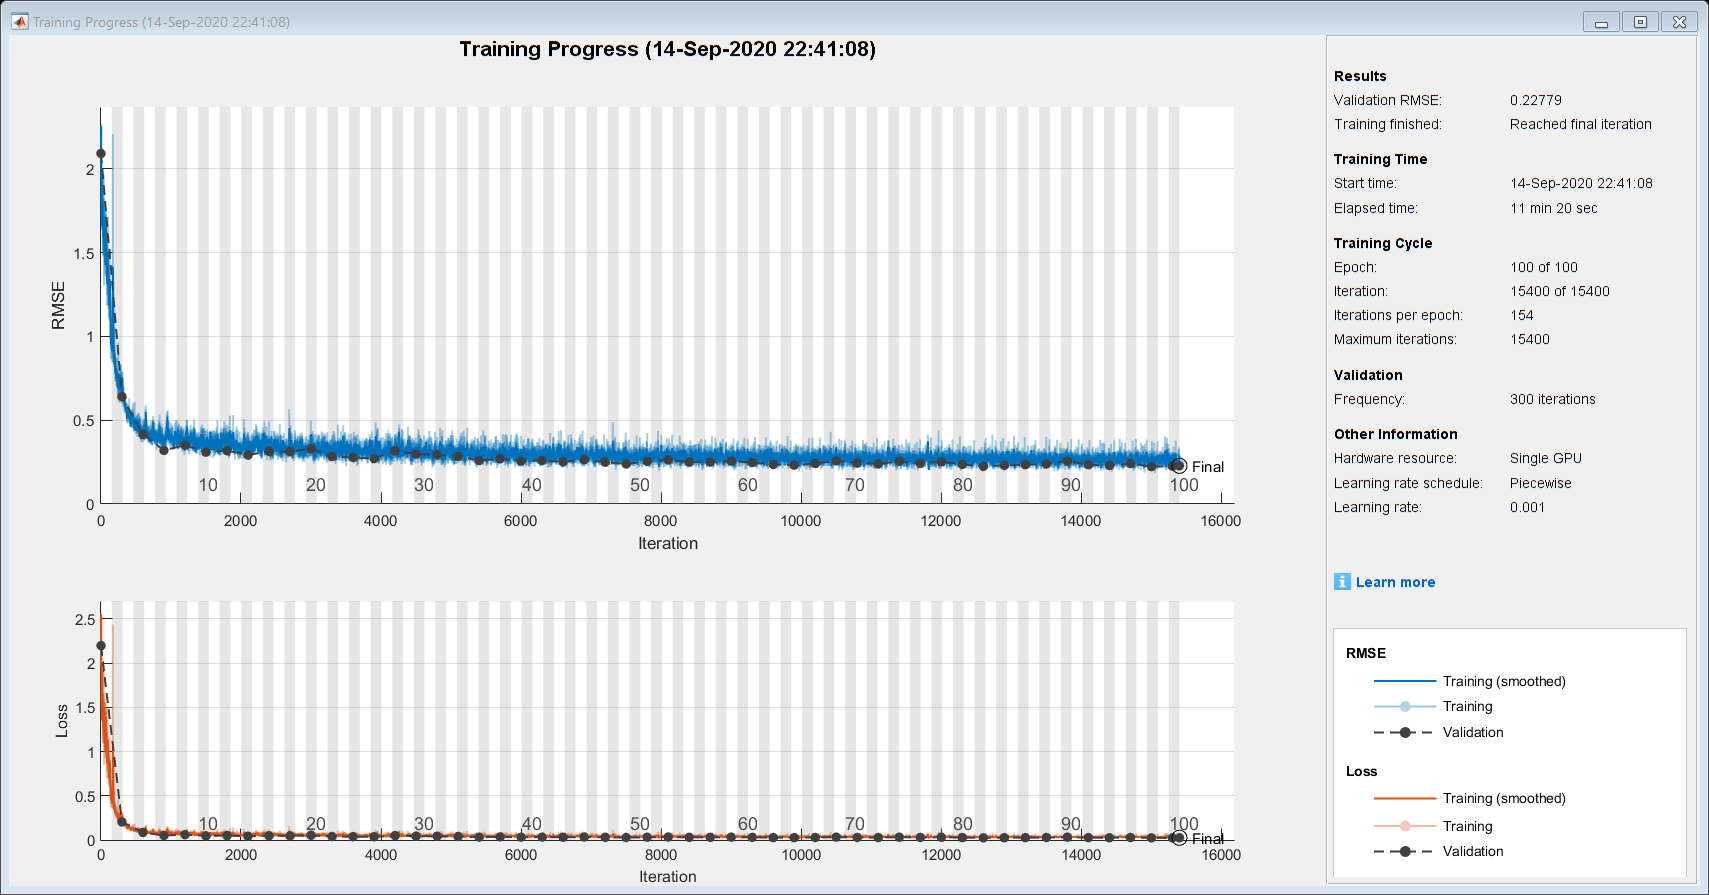

layers = [sequenceInputLayer(size(NetInput{1},1))       % Dims entrada: 2004
          gruLayer(200,'OutputMode',"sequence")         % Neuronas LSTM
          fullyConnectedLayer(50)                       % Neuronas comunes
          gruLayer(110,'OutputMode',"sequence")         % Neuronas LSTM
          dropoutLayer(0.2)                             % Neuronas que deshabilitan las salidas de neuronas previas con cierta probabilidad para evitar overfitting
          fullyConnectedLayer(size(NetOutput{1},1))     % Dims salida: 4
          regressionLayer];

% Explicación de Settings:
% - Solver: Adam. Se recomienda porque este optimizador es capaz de
%   capturar de mejor manera la dinámica de entrenamiento de redes
%   neuronales recurrentes o con memoria como las LSTMs.
% - MaxEpoch: Cantidad de "iteraciones" o pasadas que hace sobre la data.
% - MiniBatchSize: Cuantas muestras simultáneas se le pueden llegar a pasar
%   a la red a la vez. 
% - Shuffle: Never. Se evita que el entrenador re-ordene los inputs y
%   outputs que previamente fueron ordenados en el script
%   "Generar_Dataset".
% - InitialLearnRate: Valor inicial para el learning rate. 
% - LearnRateSchedule: El learn rate baja de forma periódica a lo largo del
%   entrenamiento. 'LearnRateDropPeriod' consiste de cada cuantas "Epochs"
%   el algoritmo disminuye el learning rate. 'LearnRateDropFactor' es el
%   porcentaje que se le multiplica al learning rate para reducirlo.
options = trainingOptions('adam','MaxEpoch',100,'GradientThreshold',1,...
                          'MiniBatchSize',50, ...
                          'ValidationData',{TestInput, TestOutput}, ...
                          'ValidationFrequency', 300, ...
                          'InitialLearnRate',0.001,'LearnRateSchedule',"piecewise",...
                          "LearnRateDropPeriod",1500,'LearnRateDropFactor',0.2, ...
                          'Plots',"training-progress",'Verbose',0);
                      
GRU = trainNetwork(NetInput,NetOutput,layers,options);

save("Deep PSO Tuner\Modelos\GRU - Modelo",'GRU');


## Prueba 2: Entrenamiento de LSTM Bidireccional

A bidirectional LSTM (BiLSTM) layer learns bidirectional long-term dependencies between time steps of time series or sequence data. These dependencies can be useful when you want the network to learn from the complete time series at each time step.

layers = [sequenceInputLayer(size(NetInput{1},1))       % Dims entrada: 2004
          bilstmLayer(200)                              % Neuronas LSTM
          fullyConnectedLayer(50)                       % Neuronas comunes
          bilstmLayer(110,'OutputMode',"sequence")      % Neuronas LSTM
          dropoutLayer(0.2)                             % Neuronas que deshabilitan las salidas de neuronas previas con cierta probabilidad para evitar overfitting
          fullyConnectedLayer(size(NetOutput{1},1))     % Dims salida: 4
          regressionLayer];

% Explicación de Settings:
% - Solver: Adam. Se recomienda porque este optimizador es capaz de
%   capturar de mejor manera la dinámica de entrenamiento de redes
%   neuronales recurrentes o con memoria como las LSTMs.
% - MaxEpoch: Cantidad de "iteraciones" o pasadas que hace sobre la data.
% - MiniBatchSize: Cuantas muestras simultáneas se le pueden llegar a pasar
%   a la red a la vez. 
% - Shuffle: Never. Se evita que el entrenador re-ordene los inputs y
%   outputs que previamente fueron ordenados en el script
%   "Generar_Dataset".
% - InitialLearnRate: Valor inicial para el learning rate. 
% - LearnRateSchedule: El learn rate baja de forma periódica a lo largo del
%   entrenamiento. 'LearnRateDropPeriod' consiste de cada cuantas "Epochs"
%   el algoritmo disminuye el learning rate. 'LearnRateDropFactor' es el
%   porcentaje que se le multiplica al learning rate para reducirlo.
options = trainingOptions('adam','MaxEpoch',100,'GradientThreshold',1,...
                          'MiniBatchSize',50, ...
                          'ValidationData',{TestInput, TestOutput}, ...
                          'ValidationFrequency', 300, ...
                          'InitialLearnRate',0.001,'LearnRateSchedule',"piecewise",...
                          "LearnRateDropPeriod",1500,'LearnRateDropFactor',0.2, ...
                          'Plots',"training-progress",'Verbose',0);
                      
BiLSTM = trainNetwork(NetInput,NetOutput,layers,options);
save("Deep PSO Tuner\Modelos\BiLSTM - Modelo",'BiLSTM');

## Prueba 3: Entrenamiento de LSTM

An LSTM layer learns long-term dependencies between time steps in time series and sequence data.

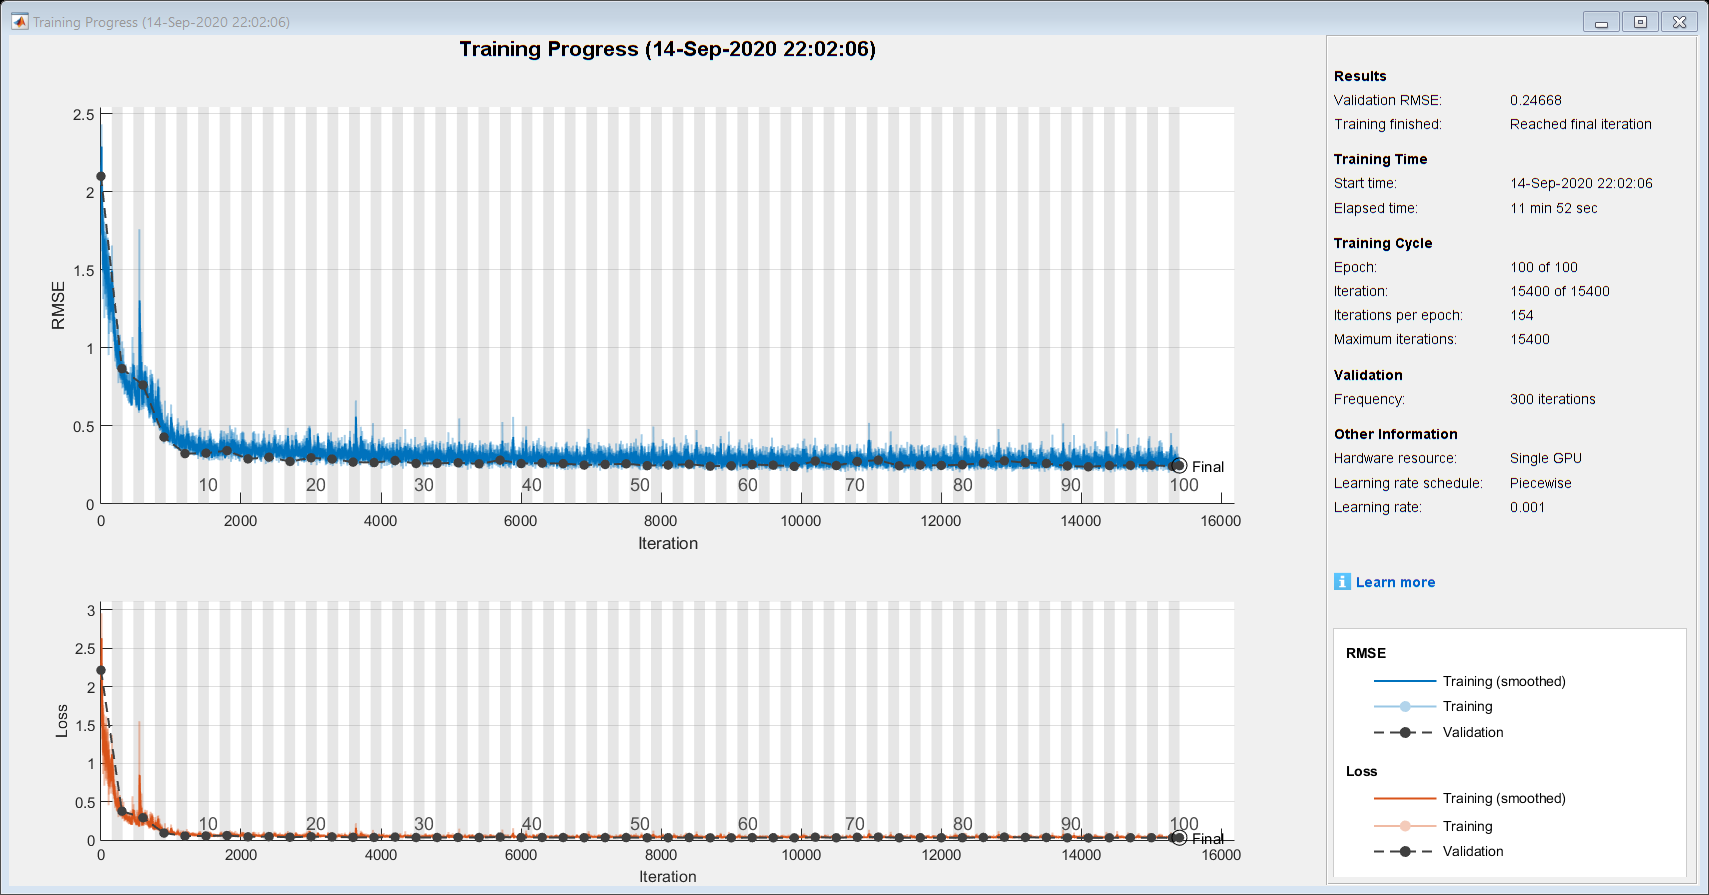

layers = [sequenceInputLayer(size(NetInput{1},1))       % Dims entrada: 2004
          lstmLayer(200,'OutputMode',"sequence")        % Neuronas LSTM
          fullyConnectedLayer(50)                       % Neuronas comunes
          lstmLayer(110,'OutputMode',"sequence")        % Neuronas LSTM
          dropoutLayer(0.2)                             % Neuronas que deshabilitan las salidas de neuronas previas con cierta probabilidad para evitar overfitting
          fullyConnectedLayer(size(NetOutput{1},1))     % Dims salida: 4
          regressionLayer];

% Explicación de Settings:
% - Solver: Adam. Se recomienda porque este optimizador es capaz de
%   capturar de mejor manera la dinámica de entrenamiento de redes
%   neuronales recurrentes o con memoria como las LSTMs.
% - MaxEpoch: Cantidad de "iteraciones" o pasadas que hace sobre la data.
% - MiniBatchSize: Cuantas muestras simultáneas se le pueden llegar a pasar
%   a la red a la vez. 
% - Shuffle: Never. Se evita que el entrenador re-ordene los inputs y
%   outputs que previamente fueron ordenados en el script
%   "Generar_Dataset".
% - InitialLearnRate: Valor inicial para el learning rate. 
% - LearnRateSchedule: El learn rate baja de forma periódica a lo largo del
%   entrenamiento. 'LearnRateDropPeriod' consiste de cada cuantas "Epochs"
%   el algoritmo disminuye el learning rate. 'LearnRateDropFactor' es el
%   porcentaje que se le multiplica al learning rate para reducirlo.
options = trainingOptions('adam','MaxEpoch',100,'GradientThreshold',1,...
                          'MiniBatchSize',50, ...
                          'ValidationData',{TestInput, TestOutput}, ...
                          'ValidationFrequency', 300, ...
                          'InitialLearnRate',0.001,'LearnRateSchedule',"piecewise",...
                          "LearnRateDropPeriod",1500,'LearnRateDropFactor',0.2, ...
                          'Plots',"training-progress",'Verbose',0);
                      
% Se entrena y guarda la red neuronal.
LSTM = trainNetwork(NetInput,NetOutput,layers,options);

save("Deep PSO Tuner\Modelos\LSTM - Modelo",'LSTM');